clear all;clc;
startTime = datetime(2025,6,30,0,0,0);
stopTime = startTime + hours(36);
sampleTime = 30;%seconds
sc = satelliteScenario(startTime,stopTime,sampleTime);
satelliteScenarioViewer(sc);

Add the satellites

%   Adding satellite #1
%   a = R_E + h
R_E = 6378e3; % meters
h = 600e3; % meters
semiMajorAxis = R_E + h;
eccentricity = 0; % circular orbit (degrees)
inclination = -70; % no inclination (degrees)
rightAscensionOfAscendingNode = 0; % no rotation of orbit (degrees)
argumentOfPeriapsis = 0;
trueAnomaly = 0; % satellite is on the perigee point (degrees)

sat1 = satellite(sc,semiMajorAxis,eccentricity,inclination,...
    rightAscensionOfAscendingNode,argumentOfPeriapsis,trueAnomaly,...
    "Name","Satellite 1",...
    "OrbitPropagator","sgp4");

% semiMajorAxis = R_E + h;
% eccentricity = 0;
% inclination = 70;
% rightAscensionOfAscendingNode = 120;
% argumentOfPeriapsis = 0;
% trueAnomaly = 300;

% sat2 = satellite(sc,semiMajorAxis,eccentricity,inclination,...
%     rightAscensionOfAscendingNode,argumentOfPeriapsis,trueAnomaly,...
%     "Name","Satellite 2",...
%     "OrbitPropagator","sgp4");

% satelliteScenarioViewer(sc);

Adding gimbals to satellites, in order to append receivers and transmitters for satellite enabled communication

gimbalSat1Tx = gimbal(sat1, ...
    "MountingLocation",[0;1;2]);  % meters
% gimbalSat2Tx = gimbal(sat2, ...
%     "MountingLocation",[0;1;2]);  % meters
gimbalSat1Rx = gimbal(sat1, ...
    "MountingLocation",[0;-1;2]); % meters
% gimbalSat2Rx = gimbal(sat2, ...
%     "MountingLocation",[0;-1;2]); % meters

sat1Rx = receiver(gimbalSat1Rx, ...
    "MountingLocation",[0;0;1], ...      % meters
    "GainToNoiseTemperatureRatio",3, ... % decibels/Kelvin
    "RequiredEbNo",4);                   % decibels
% sat2Rx = receiver(gimbalSat2Rx, ...
%     "MountingLocation",[0;0;1], ...      % meters
%     "GainToNoiseTemperatureRatio",3, ... % decibels/Kelvin
%     "RequiredEbNo",4);                   % decibels

gaussianAntenna(sat1Rx, ...
    "DishDiameter",0.5);    % meters
% gaussianAntenna(sat2Rx, ...
%     "DishDiameter",0.5);    % meters

sat1Tx = transmitter(gimbalSat1Tx, ...
    "MountingLocation",[0;0;1], ...   % meters
    "Frequency",30e9, ...             % hertz
    "Power",15);                      % decibel watts
% sat2Tx = transmitter(gimbalSat2Tx, ...
%     "MountingLocation",[0;0;1], ...   % meters
%     "Frequency",27e9, ...             % hertz
% %     "Power",15);                      % decibel watts

gaussianAntenna(sat1Tx, ...
    "DishDiameter",0.5);    % meters
% gaussianAntenna(sat2Tx, ...
%     "DishDiameter",0.5);    % meters

Add the ground stations, which is in a high foliage environment

%   Add the first ground station to the Pavliani Forest
lat = 38.7404;
lon = 22.3376;
%   The VSAT is positioned in a high place. The elevation angle
%   is the minimum angle based on 3GPP T.R.
gs1 = groundStation(sc, ...
    lat, ...
    lon, ...
    "MinElevationAngle",5,...
    "Name","PavlianiWSN");

%   Add the second ground station to the Lamia DIT Campus
lat=38.875941904578895;
lon=22.437526584061686;
%   Sub-urban environment, the elevation angle is set to 10!
minElevationAngle = 10;
gs2 = groundStation(sc,lat,lon,"MinElevationAngle",minElevationAngle,"Name","Lamia Base Station");

%   We need to also add Gimbals to each Ground Station
gimbalGs1 = gimbal(gs1, ...
    "MountingAngles",[0;180;0], ... % degrees
    "MountingLocation",[0;0;-5]);   % meters

gimbalGs2 = gimbal(gs2, ...
    "MountingAngles",[0;180;0], ... % degrees
    "MountingLocation",[0;0;-5]);   % meters

gs1Tx = transmitter(gimbalGs1, ...
    "Name","Ground Station 1 Transmitter", ...
    "MountingLocation",[0;0;1], ...           % meters
    "Frequency",30e9, ...                     % hertz
    "Power",30);                              % decibel watts

gaussianAntenna(gs1Tx, ...
    "DishDiameter",2); % meters

gs2Rx = receiver(gimbalGs2, ...
    "Name","Ground Station 2 Receiver", ...
    "MountingLocation",[0;0;1], ...        % meters
    "GainToNoiseTemperatureRatio",3, ...   % decibels/Kelvin
    "RequiredEbNo",1);                     % decibels

gaussianAntenna(gs2Rx, ...
    "DishDiameter",2); % meters

Set tracking targets for the gimbals

pointAt(gimbalGs1,sat1);
pointAt(gimbalSat1Rx,gs1);
% pointAt(gimbalSat1Tx,sat2);
% pointAt(gimbalSat2Rx,sat1);
% pointAt(gimbalSat2Tx,gs2);
pointAt(gimbalSat1Tx,gs2)
% pointAt(gimbalGs2,sat2);
pointAt(gimbalGs2,sat1);

Add link analysis

% lnk = link(gs1Tx,sat1Rx,sat1Tx,sat2Rx,sat2Tx,gs2Rx);
lnk = link(gs1Tx,sat1Rx,sat1Tx,gs2Rx);
linkIntervals(lnk)

ans = 5×8 table
                Source                          Target               IntervalNumber         StartTime                EndTime           Duration    StartOrbit    EndOrbit
    ______________________________    ___________________________    ______________    ____________________    ____________________    ________    __________    ________

    "Ground Station 1 Transmitter"    "Ground Station 2 Receiver"          1           30-Jun-2025 01:21:30    30-Jun-2025 01:25:00      210          NaN          NaN   
    "Ground Station 1 Transmitter"    "Ground Station 2 Receiver"          2           30-Jun-2025 02:58:30    30-Jun-2025 03:06:30      480          NaN          NaN   
    "Ground Station 1 Transmitt

play(sc);

Plot link margin at Ground Station 2

% [e, time] = ebno(lnk);
% margin = e - gs2Rx.RequiredEbNo;
% plot(time,margin,"LineWidth",2);
% xlabel("Time");
% ylabel("Link Margin (dB)");
% grid on;
% Step 1: Calculate Eb/No and time as before
% [e, time] = ebno(lnk);
% margin = e - gs2Rx.RequiredEbNo;
% 
% % Step 2: Get the access intervals
% ac = access(sat1, gs2); % Access object between ground station and satellite
% intv = accessIntervals(ac) % Returns start and end times of access windows
% 
% % Step 3: Find indices where time is within access intervals
% inAccess = false(size(time));
% for i = 1:height(intv)
%     startTime = intv.StartTime(i);
%     endTime = intv.EndTime(i);
%     inAccess = inAccess | (time >= startTime & time <= endTime);
% end
% 
% % Step 4: Plot only the points during access
% plot(time(inAccess), margin(inAccess), 'LineWidth', 2);
% xlabel('Time');
% ylabel('Link Margin (dB)');
% grid on;

Latency calculation

% Step 1: Calculate latency and time
[delay, time] = latency(sat1,gs1); % Assuming lnk is your satellite link
[latency2,time2] = latency(sat1,gs2);

% Step 2: Get access intervals
ac = access(gs1, sat1);
intv = accessIntervals(ac);
ac2 = access(gs2,sat1);
intv2 = accessIntervals(ac2);

% Step 3: Plot latency per pass
figure;
hold on;
avg_pass_duration = 0;
number_of_passes = 0;
avg_latency = 0;
for i = 1:height(intv)
    % Extract start and end time of the i-th pass
    startTime = intv.StartTime(i);
    endTime = intv.EndTime(i);
    avg_pass_duration = avg_pass_duration + (endTime - startTime);
    number_of_passes = number_of_passes + 1;
    % Find indices within this pass
    idx = (time >= startTime) & (time <= endTime);
    avg_latency = avg_latency + sum(delay(idx));
    % Plot latency for this pass
    plot(time(idx), delay(idx), 'LineWidth', 2, 'DisplayName', sprintf('Pass %d', i));
end

for i = 1:height(intv2)
    startTime = intv2.StartTime(i);
    endTime = intv2.EndTime(i);
    idx = (time >= startTime) & (time <= endTime);
    avg_latency = avg_latency + sum(latency2(idx));
end

avg_pass_duration/number_of_passes

ans = duration
   00:07:51


avg_latency/number_of_passes

ans = 0.1393

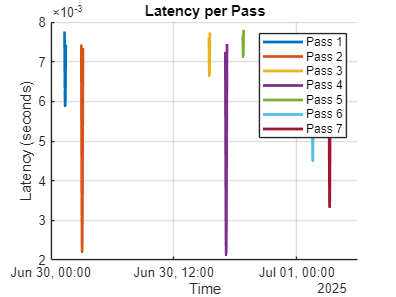

% Final plot formatting
xlabel('Time');
ylabel('Latency (seconds)');
title('Latency per Pass');
grid on;
legend('show');
hold off;